# Figure 1E

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';


load([dataDir filesep 'A010_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 20×5 cell array
    {'siCtrl DMSO'         }    {[1 2 3 4]}    {[2]}    {[1]}    {[0 0 0]}
    {'siCtrl DOX'          }    {[5 6 7 8]}    {[2]}    {[1]}    {[0 0 0]}
    {'siCCNE/siCtrl DMSO'  }    {[1 2 3 4]}    {[3]}    {[1]}    {[0 0 0]}
    {'siCCNE/siCtrl DOX'   }    {[5 6 7 8]}    {[3]}    {[1]}    {[0 0 0]}
    {'siCCNA/siCtrl DMSO'  }    {[1 2 3 4]}    {[4]}    {[1]}    {[0 0 0]}
    {'siCCNA/siCtrl DOX'   }    {[5 6 7 8]}    {[4]}    {[1]}    {[0 0 0]}
    {'siSkp2/siCCNA DMSO'  }    {[1 2 3 4]}    {[5]}    {[1]}    {[0 0 0]}
    {'siSkp2/siCCNA DOX'   }    {[5 6 7 8]}    {[5]}    {[1]}    {[0 0 0]}
    {'siSkp2/siCDC25a DMSO'}    {[1 2 3 4]}    {[6]}    {[1]}    {[0 0 0]}
    {'siSkp2/siCDC25a DOX' }    {[5 6 7 8]}    {[6]}    {[1]}    {[0 0 0]}
    {'siCDC25a/siCCNA DMSO'}    {[1 2 3 4]}    {[7]}    {[1]}    {[0 0 0]}
    {'siCDC25a/siCCNA DOX' }    {[5 6 7 8]}    {[7]}    {[1]}    {[0 0 0]}
    {'siCCNA/siCCNE DMSO'  }    {[1 2 3 4]}    {[8]}    {[1]}    {[0 0 


framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
   
    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
     

    end
    S(i).apcExpressGate = apcExpressGate;
  

end

S-APC


colors =  [.1 .3 1];
f1=figure ('units','inches','position',[0 0 4 4]);

conds=[1];
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 20];
 
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) & ~isnan(data.POI(:,2)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) &...
       data.apcExpressGate & data.goodCdk;

    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,2));
    yvals = yvals(yvals < 10 & yvals > -10);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
   cols = colors(1,:);
    groupcol = colors(1,:);
 sum(inds)

end

ans = 5030

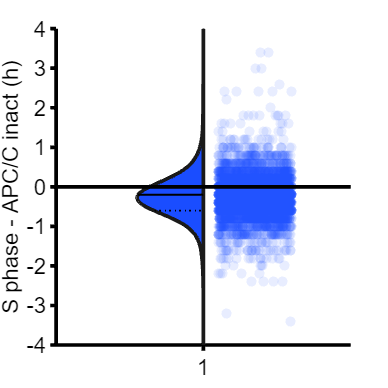

figure(f1)
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.25,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',2)
set(h{1},{'FaceColor'},{cols})
hold on
jit = 0.5*rand(size(groups)) + .1;
scatter(groups+jit, (ally),30,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'S phase - APC/C inact (h)'])

hline(0,'k')

yticks(-5:1:5)
ylim([-4 4])
set(gca, 'color','white','XColor','black','Ycolor','black','fontsize',12)




 % print_pdf(['fig_1E.pdf'])